Temporary file 2 : Centralized Dissipativation of the Platoon

clear all
load tempNet.mat

obj = net.platoons(1)
% Number of follower vehicles
N = obj.numOfVehicles-1; 

% Whether to use a soft or hard graph constraint
isSoft = 1;

% Desired noise attenuation level: L2Gain from w to e
gammaSqBar = 0.5;

% Passivity indices type
% With local controllers - II: rho = 0, nu = -1/2 (this approach can stabilize)
nu = -10;
nuVals = nu*ones(N,1);
rho = 4;
rhoVals = rho*ones(N,1);
obj.loadPassivityIndices(nuVals,rhoVals);


% Creating the adgacency matrix, null matrix and cost matrix
G = obj.topology.graph;
A = adjacency(G);
for i = 1:1:N
    for j = 1:1:N
        % Structure of K_ij (which is a 3x3 matrix) should be embedded here
        if i~=j
            if A(i+1,j+1)==1
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 0.01*[0,0,0; 0,0,0; 1,1,1];
            else
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 0,0,0];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 1*[0,0,0; 0,0,0; 1,1,1];
            end
        else
            adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
            nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
            costMatBlock{i,j} = 100*[0,0,0; 0,0,0; 1,1,1];
        end
    end 
end
adjMatBlock = cell2mat(adjMatBlock)
nullMatBlock = cell2mat(nullMatBlock)
costMatBlock = cell2mat(costMatBlock)

% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek');
I = eye(3*N);
I_n = eye(3);
O = zeros(3*N);

Q = sdpvar(3*N,3*N,'full'); 
P = sdpvar(N,N,'diagonal');
gammaSq = sdpvar(1,1,'full');
rho = sdpvar(1,1,'full');

X_p_11 = [];
X_p_12 = [];
X_12 = [];
X_p_22 = [];
for i = 1:1:N
    nu_i = obj.vehicles(i+1).nu;
    rho_i = obj.vehicles(i+1).rho;

    X_p_11 = blkdiag(X_p_11,-nu_i*P(i,i)*I_n);
    X_p_12 = blkdiag(X_p_12,0.5*P(i,i)*I_n);
    X_12 = blkdiag(X_12,(-1/(2*nu_i))*I_n);
    X_p_22 = blkdiag(X_p_22,-rho_i*P(i,i)*I_n);
end
X_p_21 = X_p_12';
X_21 = X_12';

% Objective Function
costFun = norm(Q.*costMatBlock,1);

% Budget Constraints
con0 = costFun <= 1;

% Basic Constraints
con1 = P >= 0;
con2 = gammaSq >= 0;
con3 = gammaSq <= gammaSqBar;
con4 = trace(P)==1;


DMat = [X_p_11, O; O, I];
MMat = [Q, X_p_11; I, O];
ThetaMat = [-X_21*Q-Q'*X_12-X_p_22, -X_p_21; -X_p_12, gammaSq*I];
con5 = [DMat, MMat; MMat', ThetaMat] >= 0; % The real one
%     con5 = [X_p_11, X_p_11; X_p_11, gammaSq*I] >= 0; % A temp one


% Structural constraints
con6 = Q.*(nullMatBlock==1)==O;  % Structural limitations (due to the format of the control law)
con7 = Q.*(adjMatBlock==0)==O;  % Graph structure : hard constraint

% Total Cost and Constraints
if isSoft
    cons = [con0,con1,con2,con3,con4,con5,con6]; % Without the hard graph constraint con7
    costFun = 1*costFun + 1*gammaSq; % soft 
else
    cons = [con0,con1,con2,con3,con4,con5,con6,con7]; % With the hard graph constraint con7
    costFun = 1*costFun + 1*gammaSq; % hard (same as soft)
end

sol = optimize(cons,[costFun],solverOptions);
status = sol.info

PVal = value(P)
QVal = value(Q)

costFunVal = value(costFun)
gammaSqVal = value(gammaSq)

X_p_11Val = value(X_p_11)
X_p_21Val = value(X_p_21)

M_neVal = X_p_11Val\QVal

% Obtaining K_ij blocks
M_neVal(nullMatBlock==1) = 0;
maxNorm = 0;
for i = 1:1:N
    for j = 1:1:N
        K{i,j} = M_neVal(3*(i-1)+1:3*i , 3*(j-1)+1:3*j); % (i,j)-th (3 x 3) block
        normVal = max(max(abs(K{i,j})));
        if normVal>maxNorm 
            maxNorm = normVal;
        end
    end
end
maxNorm

% filtering out small interconnections
for i=1:1:N
    for j=1:1:N
        
        if i~=j
            if isSoft
                K{i,j}(abs(K{i,j})<0.000001*maxNorm) = 0;                       
            else
                if A(i+1,j+1)==0
                    K{i,j} = zeros(3);
                end
            end
        end
        
    end
end

K

Looks like there are some additional conditions on nu, rho and gammaBar values. So, lets plot nu, rho, gammaBar vs feasibility of the solution (under soft graph constraints)

clear all
load tempNet2.mat

obj = net.platoons(1)

% Number of follower vehicles
N = obj.numOfVehicles-1; 

% Creating the adgacency matrix, null matrix and cost matrix
G = obj.topology.graph;
A = adjacency(G);
for i = 1:1:N
    for j = 1:1:N
        % Structure of K_ij (which is a 3x3 matrix) should be embedded here
        if i~=j
            if A(i+1,j+1)==1
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 0.01*[0,0,0; 0,0,0; 1,1,1];
            else
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 0,0,0];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 1*[0,0,0; 0,0,0; 1,1,1];
            end
        else
            adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
            nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
            costMatBlock{i,j} = 100*[0,0,0; 0,0,0; 1,1,1];
        end
    end 
end
adjMatBlock = cell2mat(adjMatBlock)
nullMatBlock = cell2mat(nullMatBlock)
costMatBlock = cell2mat(costMatBlock)

% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek','verbose',0);
I = eye(3*N);
I_n = eye(3);
O = zeros(3*N);

%% 
isSoft = 1;

dataset = []
count = 1;
for gammaSqBar = 0.1:0.1:1
    for nu = -0.1:-0.5:-10.1 %-0.1:-0.2:-5 %-1:-5:-101
        for rho = 0.1:0.5:10.1 %0.1:0.2:5 %1:5:101
                        
            Q = sdpvar(3*N,3*N,'full'); 
            P = sdpvar(N,N,'diagonal');
            gammaSq = sdpvar(1,1,'full');
            
            X_p_11 = [];
            X_p_12 = [];
            X_12 = [];
            X_p_22 = [];
            for i = 1:1:N            
                X_p_11 = blkdiag(X_p_11,-nu*P(i,i)*I_n);
                X_p_12 = blkdiag(X_p_12,0.5*P(i,i)*I_n);
                X_12 = blkdiag(X_12,(-1/(2*nu))*I_n);
                X_p_22 = blkdiag(X_p_22,-rho*P(i,i)*I_n);
            end
            X_p_21 = X_p_12';
            X_21 = X_12';
            
            % Objective Function
            costFun = norm(Q.*costMatBlock,1);
            
            % Budget Constraints
            con0 = costFun <= 1;
            
            % Basic Constraints
            con1 = P >= 0;
            con2 = gammaSq >= 0;
            con3 = gammaSq <= gammaSqBar;
            con4 = trace(P)==1;
                        
            DMat = [X_p_11, O; O, I];
            MMat = [Q, X_p_11; I, O];
            ThetaMat = [-X_21*Q-Q'*X_12-X_p_22, -X_p_21; -X_p_12, gammaSq*I];
            con5 = [DMat, MMat; MMat', ThetaMat] >= 0; % The real one
            
            % Structural constraints
            con6 = Q.*(nullMatBlock==1)==O;  % Structural limitations (due to the format of the control law)
            con7 = Q.*(adjMatBlock==0)==O;  % Graph structure : hard constraint
            
            % Total Cost and Constraints
            if isSoft
                cons = [con1,con2,con3,con4,con5,con6]; % Without the hard graph constraint con7
                costFun = 1*costFun + 1*gammaSq; % soft 
            else
                cons = [con1,con2,con3,con4,con5,con6,con7]; % With the hard graph constraint con7
                costFun = 1*costFun + 1*gammaSq; % hard (same as soft)
            end
            
            sol = optimize(cons,[costFun],solverOptions);
%             status = sol.info;
            
%             PVal = value(P);
%             QVal = value(Q);
%             
%             costFunVal = value(costFun);
%             gammaSqVal = value(gammaSq);
%             
%             X_p_11Val = value(X_p_11);
%             X_p_21Val = value(X_p_21);
%             
%             M_neVal = X_p_11Val\QVal;
%            
%             % Obtaining K_ij blocks
%             M_neVal(nullMatBlock==1) = 0;
            
            % Data set collecting
            dataset = [dataset; sol.problem==0,gammaSqBar,nu,rho];
            count = count + 1
        end
    end
end

Plotting Feasible/infeasible nu,rho and gamma combinations

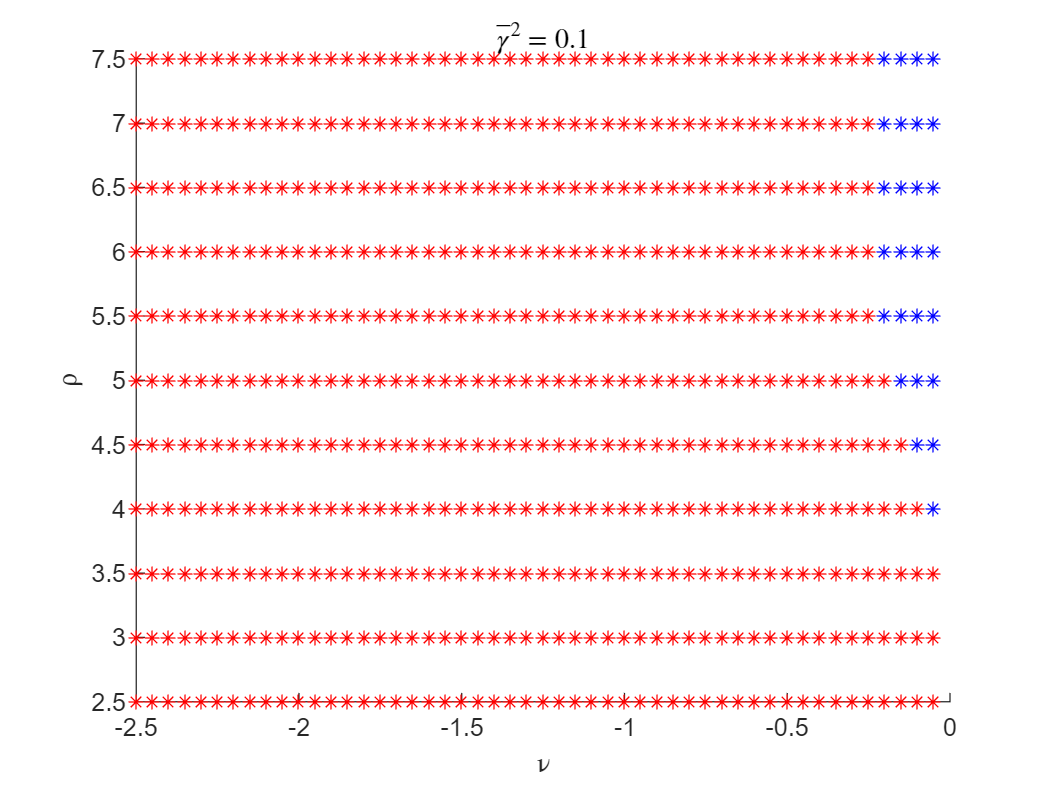

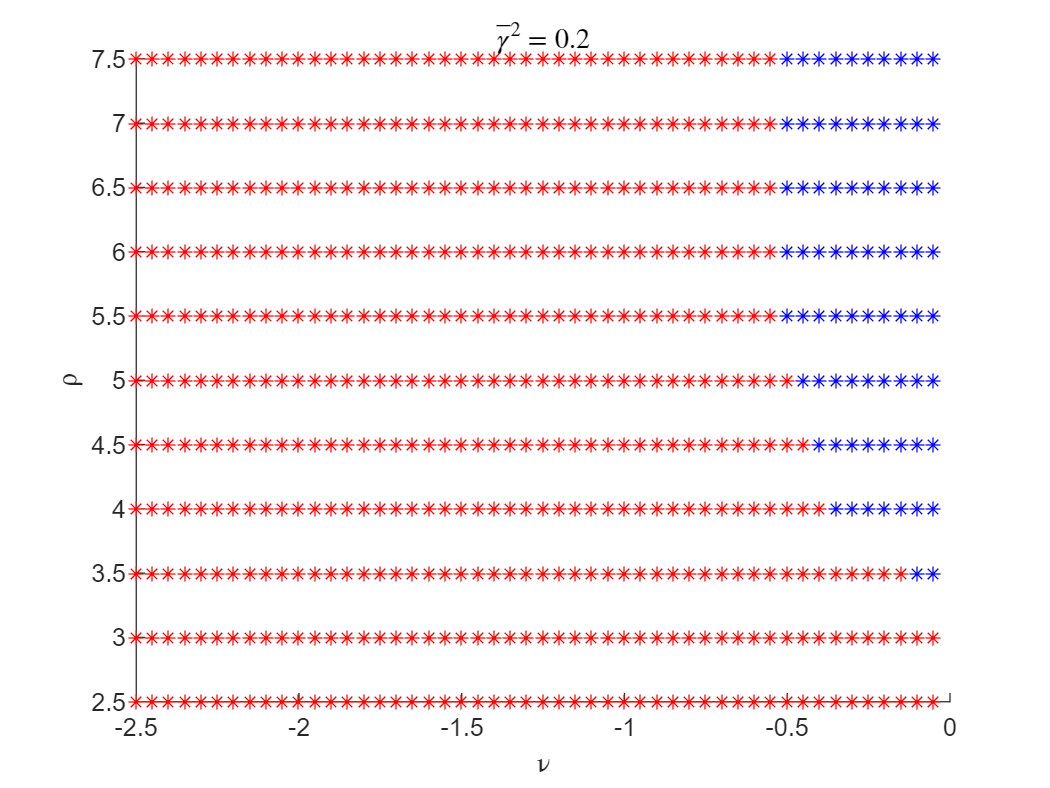

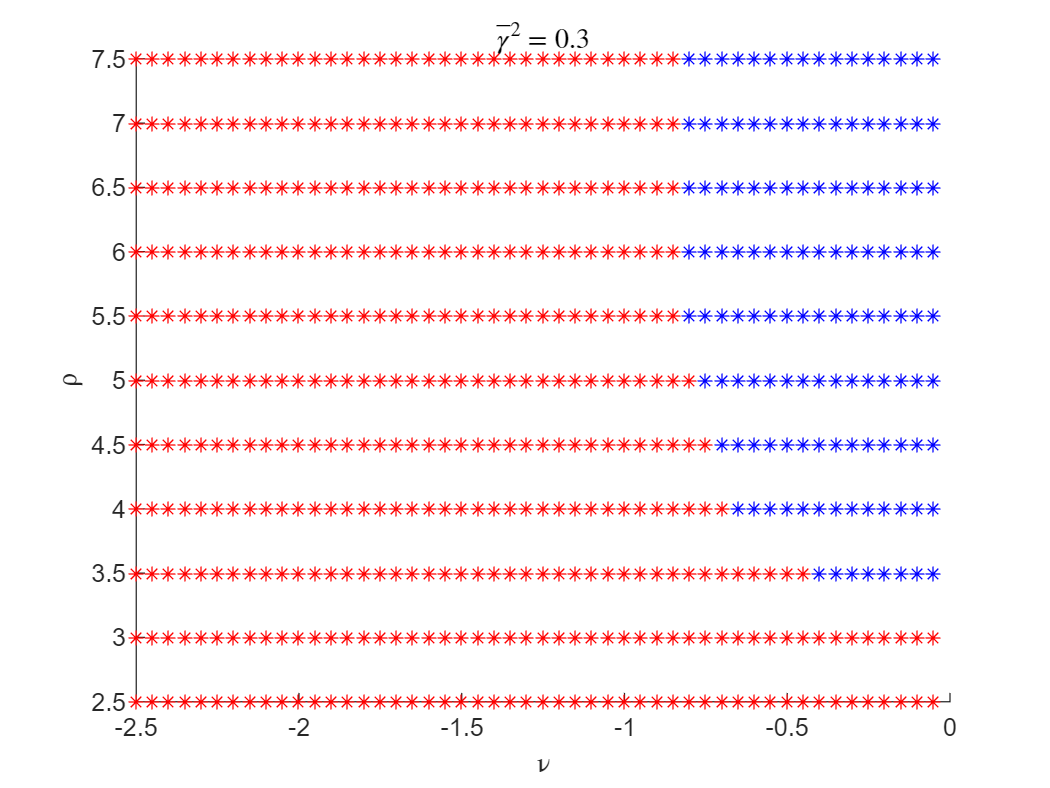

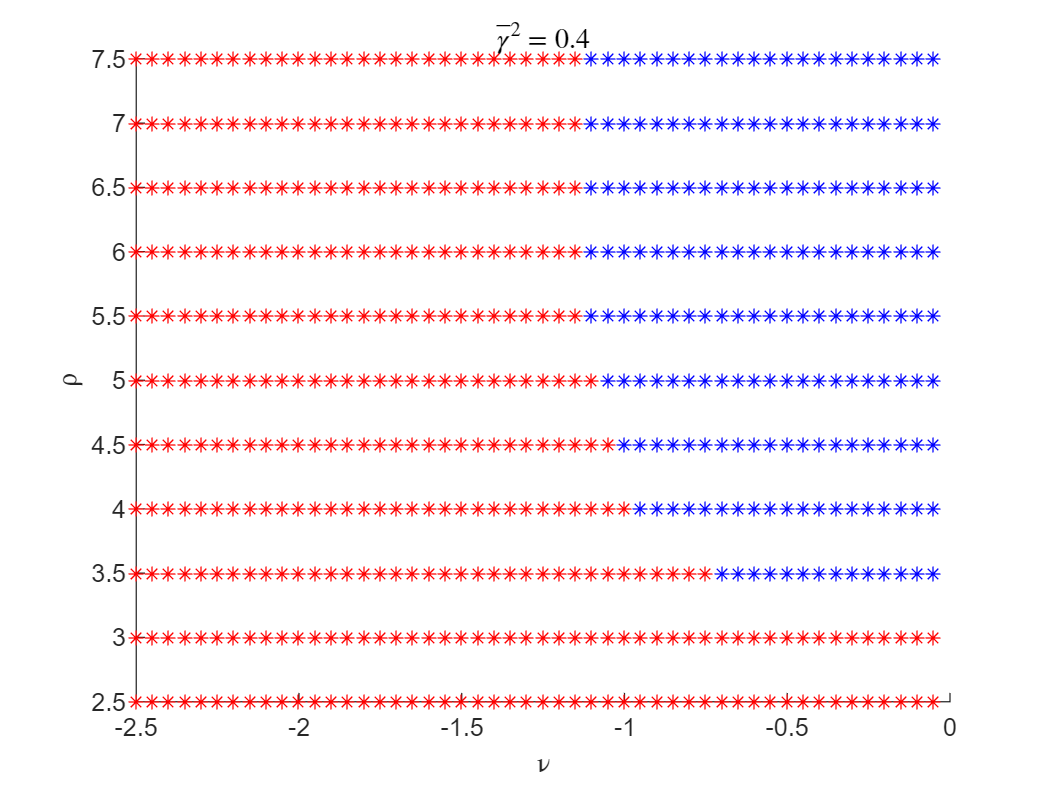

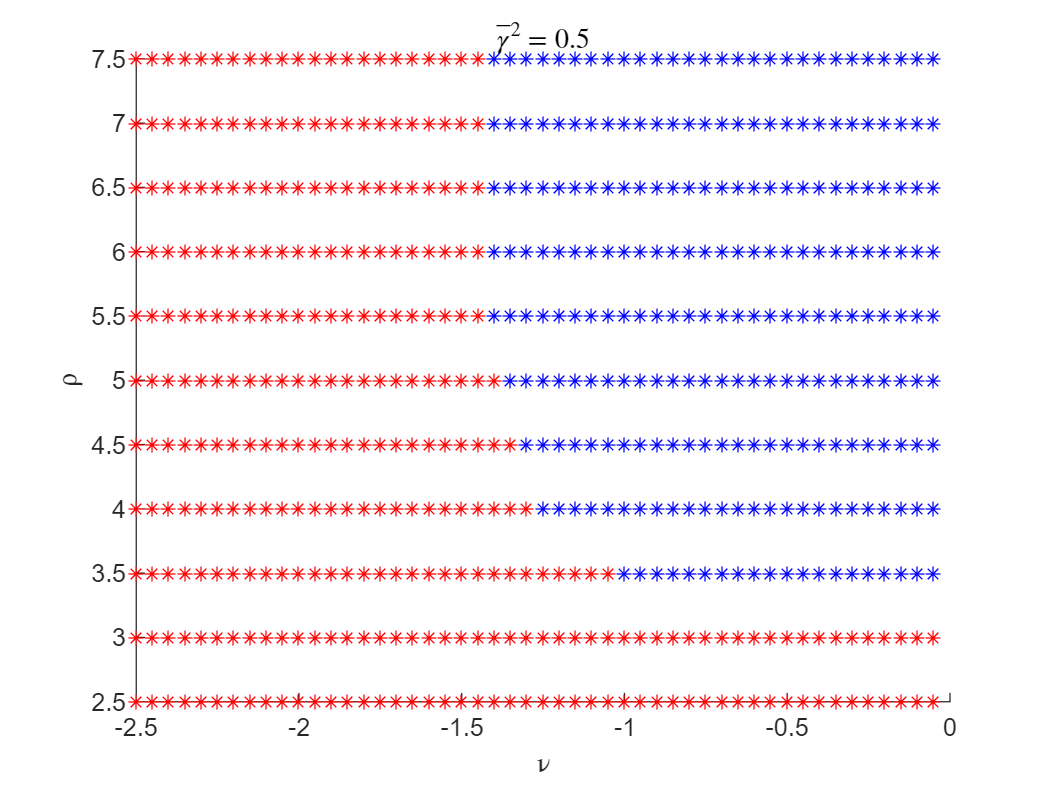

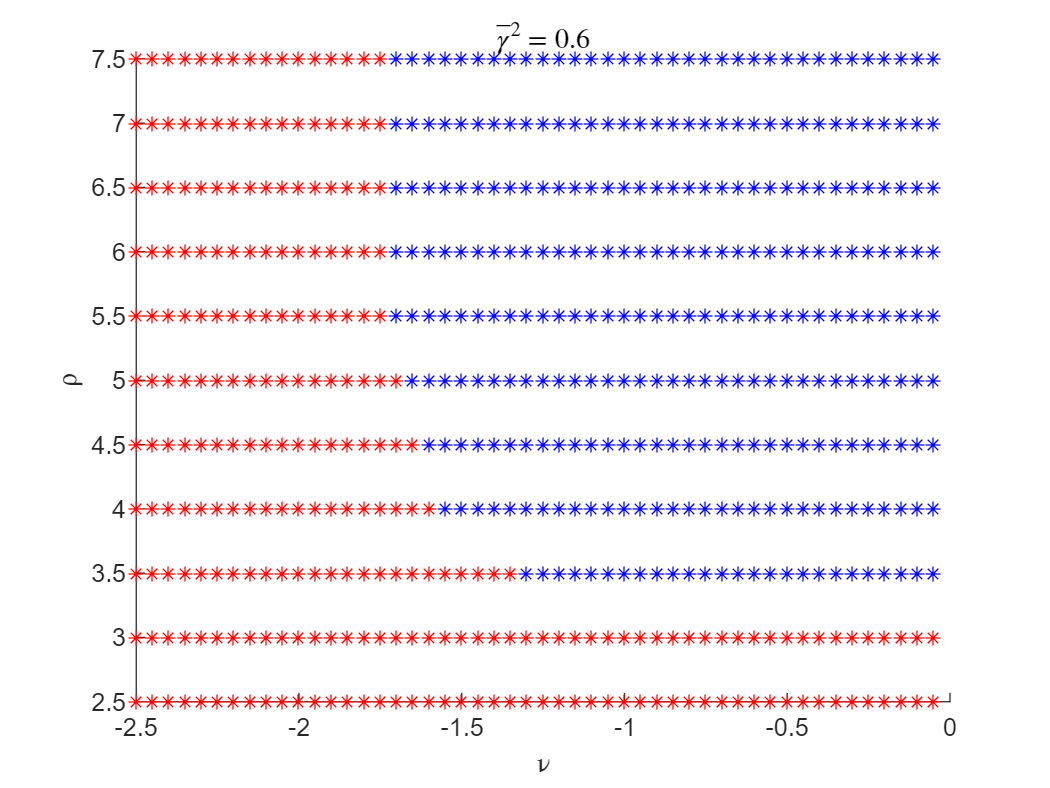

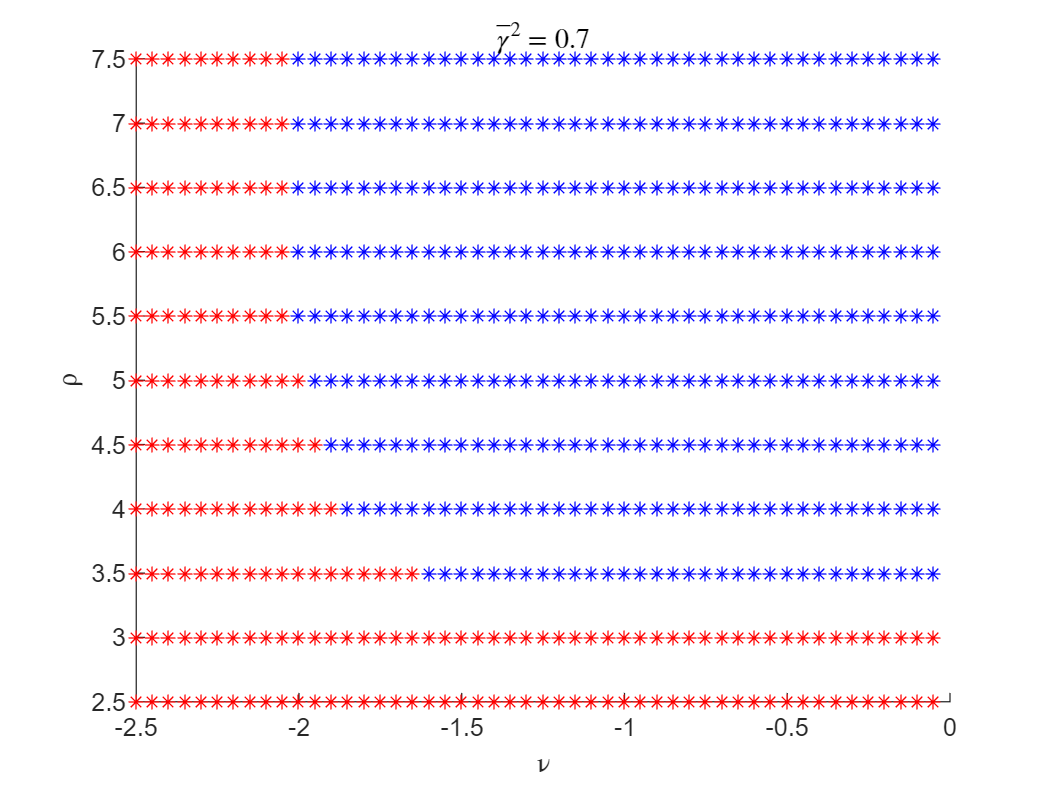

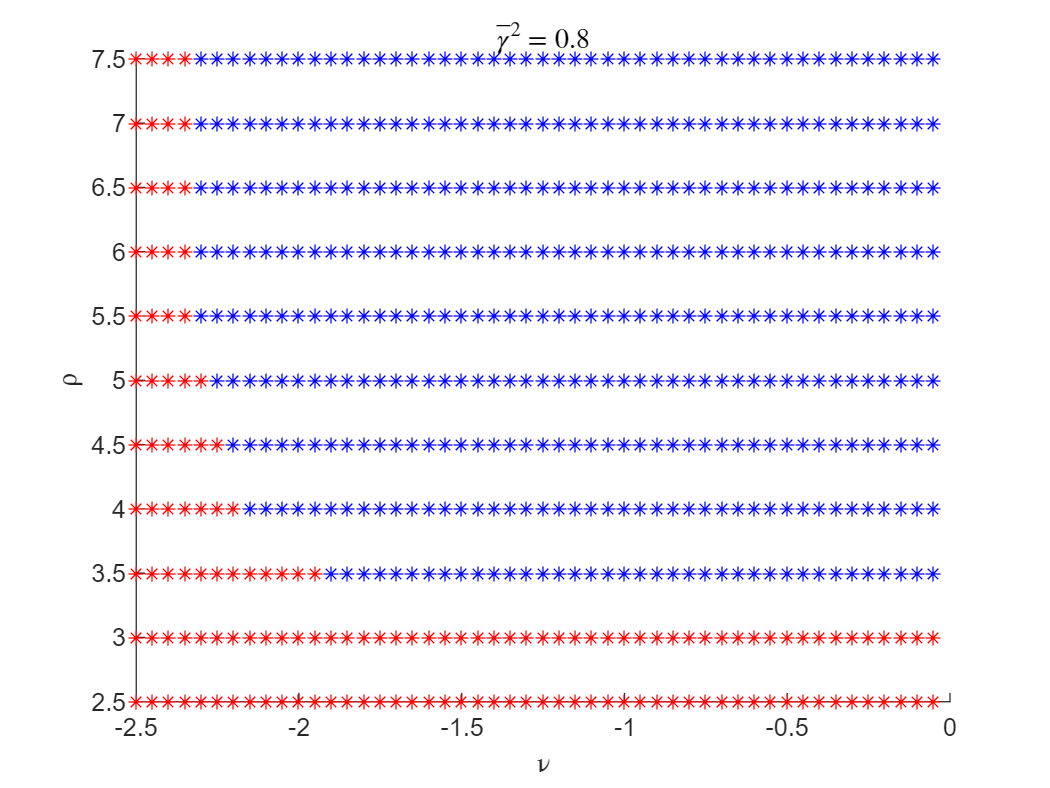

clear all
load dataset2.mat

success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

for gammaVal = 0.1:0.1:1

    successVals = success(gammas==gammaVal);
    nuVals = nus(gammas==gammaVal);
    rhoVals = rhos(gammas==gammaVal);
    
    figure
    hold on
    for i = 1:1:length(nuVals)
        if successVals(i) == 1
            plot(nuVals(i),rhoVals(i),'*b')
        else
            plot(nuVals(i),rhoVals(i),'*r')
        end
    end
    xlabel('\nu')
    ylabel('\rho')
    title(['$\bar{\gamma}^2=$',num2str(gammaVal)], 'interpreter', 'latex')
    
end

Looking at local design, what are achievable (nu,rho) values based on the error dynamics and feedback control mechanism we use?

clear all

% Local Error Dynamics
A = [0,1,0;0,0,1;0,0,0];
B = [0;0;1];
I = eye(3);
O = zeros(3);

% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek','verbose',0);

datasetL = [];
count = 1;

for nuVal = -0.1:-0.5:-10.1 %-0.1:-0.2:-5 %-1:-5:-101
    for rhoVal = 0.1:0.5:10.1 %0.1:0.2:5 %1:5:101

        P = sdpvar(3,3,'symmetric'); 
        K = sdpvar(1,3,'full'); 
        rhoBar = sdpvar(1,1,'full'); %Representing: 1/rho
        nu = sdpvar(1,1,'full');

        % X_11 = -nu*I;
        % X_22 = -rho*I;
        % X_12 = 0.5*I;
        % X_21 = X_12';

        % Basic Constraints
        con1 = P >= 0;
        con2 = trace(P)==1; % In this setting this is not required actually
        
        % Approach 4 with rho = prespecified, nu < 0 and nu is free to maximize
        DMat = [rhoBar*I];
        MMat = [P, O];
        ThetaMat = [-A*P-P*A'-B*K-K'*B', -I+0.5*P; -I+0.5*P, -nu*I];
        W = [DMat, MMat; MMat', ThetaMat];
        con3 = W >= 0;

        % Some modesty constraints on resulting nu and rho from the local design
        con4 = nu == nuVal;
        con5 = rhoBar == 1/rhoVal;


        % Total Cost and Constraints
        cons = [con1,con3,con4,con5];
        costFun = nu+rhoBar;

        % Solution
        sol = optimize(cons,[nu+rhoBar],solverOptions);
            
        % PVal = value(P)
        % KVal = value(K)
        % 
        % LVal = KVal/PVal
        % nuVal = value(nu)
        % rhoVal = 1/value(rhoBar)
        
        status = sol.info;
        datasetL = [datasetL; sol.problem==0, nuVal,rhoVal,value(costFun)];
        count = count + 1
    end
end     

Plotting feasible and infeasible nu,rho combinations

clear all
close all
load dataset4L.mat
success = datasetL(:,1);
nus = datasetL(:,2);
rhos = datasetL(:,3);
costs = datasetL(:,4);

figure
hold on
for i = 1:1:length(nus)
    if success(i) == 1
        plot(nus(i),rhos(i),'*b')
    else
        plot(nus(i),rhos(i),'*r')
    end
end
xlabel('\nu')
ylabel('\rho')
title('Local Design Feasibility')

load dataset4.mat
success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

gammaVal = 1

gammaVal = 1

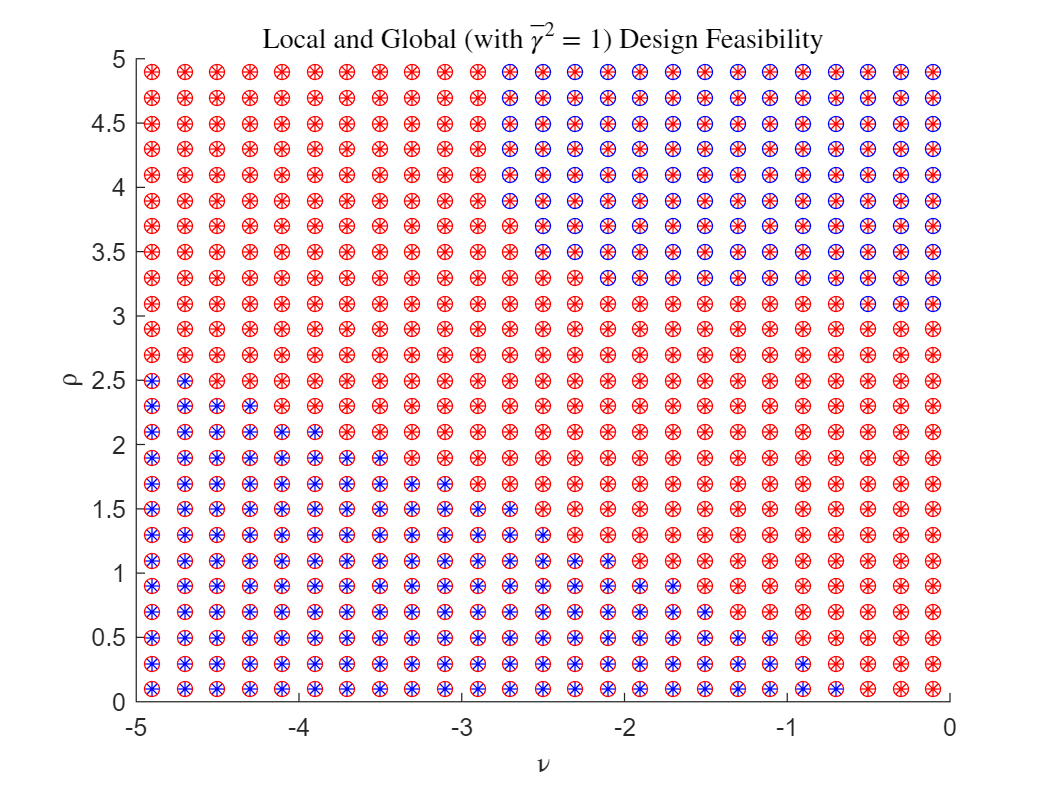


successVals = success(gammas==gammaVal);
nuVals = nus(gammas==gammaVal);
rhoVals = rhos(gammas==gammaVal);
    
for i = 1:1:length(nuVals)
    if successVals(i) == 1
        plot(nuVals(i),rhoVals(i),'ob')
    else
        plot(nuVals(i),rhoVals(i),'or')
    end    
end
title(['Local and Global (with $\bar{\gamma}^2=$',num2str(gammaVal),') Design Feasibility'], 'interpreter', 'latex')

Dataset4 and dataset4L : Focus on nu,rho when blue regions are closer, Seems there is no overlapping!

See the gamma value in the infeasible global designs.

clear all
load tempNet2.mat

obj = net.platoons(1)

% Number of follower vehicles
N = obj.numOfVehicles-1; 

% Creating the adgacency matrix, null matrix and cost matrix
G = obj.topology.graph;
A = adjacency(G);
for i = 1:1:N
    for j = 1:1:N
        % Structure of K_ij (which is a 3x3 matrix) should be embedded here
        if i~=j
            if A(i+1,j+1)==1
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 0.01*[0,0,0; 0,0,0; 1,1,1];
            else
                adjMatBlock{i,j} = [0,0,0; 0,0,0; 0,0,0];
                nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
                costMatBlock{i,j} = 1*[0,0,0; 0,0,0; 1,1,1];
            end
        else
            adjMatBlock{i,j} = [0,0,0; 0,0,0; 1,1,1];
            nullMatBlock{i,j} = [1,1,1; 1,1,1; 0,0,0];
            costMatBlock{i,j} = 100*[0,0,0; 0,0,0; 1,1,1];
        end
    end 
end
adjMatBlock = cell2mat(adjMatBlock)
nullMatBlock = cell2mat(nullMatBlock)
costMatBlock = cell2mat(costMatBlock)

% Set up the LMI problem
solverOptions = sdpsettings('solver','mosek','verbose',0);
I = eye(3*N);
I_n = eye(3);
O = zeros(3*N);

%% 
isSoft = 1;

dataset = []
count = 1;

for nu = -0.1:-0.5:-10.1 %-0.1:-0.2:-5 %-1:-5:-101
    for rho = 0.1:0.5:10.1 %0.1:0.2:5 %1:5:101
                    
        Q = sdpvar(3*N,3*N,'full'); 
        P = sdpvar(N,N,'diagonal');
        gammaSq = sdpvar(1,1,'full');
        
        X_p_11 = [];
        X_p_12 = [];
        X_12 = [];
        X_p_22 = [];
        for i = 1:1:N            
            X_p_11 = blkdiag(X_p_11,-nu*P(i,i)*I_n);
            X_p_12 = blkdiag(X_p_12,0.5*P(i,i)*I_n);
            X_12 = blkdiag(X_12,(-1/(2*nu))*I_n);
            X_p_22 = blkdiag(X_p_22,-rho*P(i,i)*I_n);
        end
        X_p_21 = X_p_12';
        X_21 = X_12';
        
        % Objective Function
        costFun = norm(Q.*costMatBlock,1);
        
        % Budget Constraints
        con0 = costFun <= 1;
        
        % Basic Constraints
        con1 = P >= 0;
        con2 = gammaSq >= 0;
%         con3 = gammaSq <= gammaSqBar;
        con4 = trace(P)==1;
                    
        DMat = [X_p_11, O; O, I];
        MMat = [Q, X_p_11; I, O];
        ThetaMat = [-X_21*Q-Q'*X_12-X_p_22, -X_p_21; -X_p_12, gammaSq*I];
        con5 = [DMat, MMat; MMat', ThetaMat] >= 0; % The real one
        
        % Structural constraints
        con6 = Q.*(nullMatBlock==1)==O;  % Structural limitations (due to the format of the control law)
        con7 = Q.*(adjMatBlock==0)==O;  % Graph structure : hard constraint
        
        % Total Cost and Constraints
        if isSoft
            cons = [con1,con2,con4,con5,con6]; % Without the hard graph constraint con7
            costFun = 1*costFun + 1*gammaSq; % soft 
        else
            cons = [con1,con2,con3,con4,con5,con6,con7]; % With the hard graph constraint con7
            costFun = 1*costFun + 1*gammaSq; % hard (same as soft)
        end
        
        sol = optimize(cons,[costFun],solverOptions);
%             status = sol.info;
        
%             PVal = value(P);
%             QVal = value(Q);
%             
%             costFunVal = value(costFun);
        gammaSqVal = value(gammaSq);
%             
%             X_p_11Val = value(X_p_11);
%             X_p_21Val = value(X_p_21);
%             
%             M_neVal = X_p_11Val\QVal;
%            
%             % Obtaining K_ij blocks
%             M_neVal(nullMatBlock==1) = 0;
        
        % Data set collecting
        dataset = [dataset; sol.problem==0,gammaSqVal,nu,rho];
        count = count + 1
    end
end

clear all
load dataset6V.mat  %dataset6V.mat for N=5

success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

gammaMat = []
nuMat = []
rhoMat = []

count = 1
for nu = -0.1:-0.5:-10.1% -0.1:-0.2:-5 %-1:-5:-101
    gammaMatRow = [];
    nuMatRow = [];
    rhoMatRow = [];
    for rho = -0.1:-0.5:-10.1% 0.1:0.2:5 %1:5:101
        if success(count) == 1
            gammaVal = gammas(count);
        else
            gammaVal = NaN;
        end
        gammaMatRow = [gammaMatRow, gammaVal];
        nuMatRow = [nuMatRow, nus(count)];
        rhoMatRow = [rhoMatRow, rhos(count)];
        count = count + 1;
    end
    gammaMat = [gammaMat; gammaMatRow];
    nuMat = [nuMat; nuMatRow];
    rhoMat = [rhoMat; rhoMatRow];
end
figure
surf(nuMat,rhoMat,gammaMat)
xlabel('\nu')
ylabel('\rho')
zlabel('\gamma')

load dataset5L.mat

success = datasetL(:,1);
nus = datasetL(:,2);
rhos = datasetL(:,3);
costs = datasetL(:,4);


hold on
for i = 1:1:length(nus)
    if success(i) == 1
        plot(nus(i),rhos(i),'*b')
    else
        plot(nus(i),rhos(i),'*r')
    end
end
% xlabel('\nu')
% ylabel('\rho')
% title('Local Design Feasibility')

load dataset6.mat %dataset6.mat for N=5
success = dataset(:,1);
gammas = dataset(:,2);
nus = dataset(:,3);
rhos = dataset(:,4);

gammaVal = 1

successVals = success(gammas==gammaVal);
nuVals = nus(gammas==gammaVal);
rhoVals = rhos(gammas==gammaVal);
    
for i = 1:1:length(nuVals)
    if successVals(i) == 1
        plot(nuVals(i),rhoVals(i),'ob')
    else
        plot(nuVals(i),rhoVals(i),'or')
    end    
end